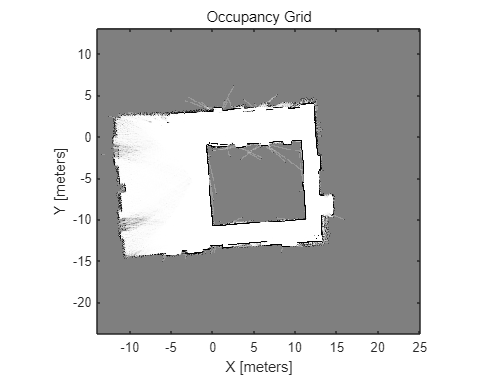

show(map)


planner = plannerAStarGrid(map);

start = [5 12];
goal = [0 2];

plan(planner,start,goal);

show(planner)

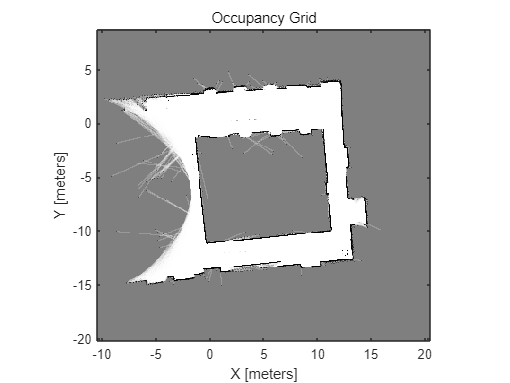

load("map.mat", "Map")
show(Map)

bounds = [Map.XWorldLimits; Map.YWorldLimits; [-pi pi]]

bounds =   -10.4886   20.5114
  -20.2309    8.7691
   -3.1416    3.1416


ss = stateSpaceDubins(bounds)

ss =   stateSpaceDubins - 속성 있음:

   SE2 Properties
                 Name: 'SE2 Dubins'
          StateBounds: [3×2 double]
    NumStateVariables: 3

   Dubins Vehicle Properties
     MinTurningRadius: 1


ss.MinTurningRadius = 0.4

ss =   stateSpaceDubins - 속성 있음:

   SE2 Properties
                 Name: 'SE2 Dubins'
          StateBounds: [3×2 double]
    NumStateVariables: 3

   Dubins Vehicle Properties
     MinTurningRadius: 0.4000


stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = Map;
stateValidator.ValidationDistance = 0.05;

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

rng default
start = [0.0,1.0,-pi];
goal = [10,2,0];
[pthObj, solnInfo] = plan(planner,start,goal);

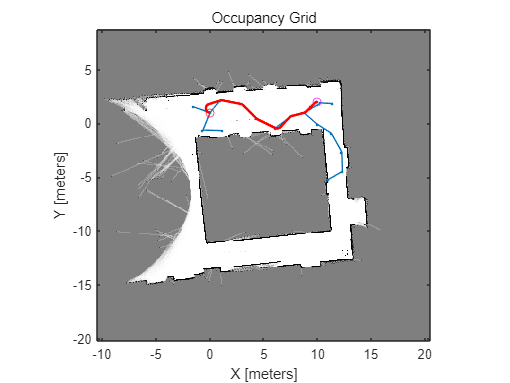

show(Map)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate and plot path.
interpolate(pthObj,300)
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
hold off

path = [2.00    1.00;
        1.25    1.75;
        5.25    8.25;
        7.25    8.75;
        11.75   10.75;
        12.00   10.00];

robotInitialLocation = path(1,:);
robotGoal = path(end,:);